# Deel 1 practicum regeltechniek 

**Auteur: Perijn Huijser**

**Datum: 25-09-2025**

**Revisie: 3**

## Changelog

Versie 1.0 - 25-09-2025

-Initiale opbouw

## Opdracht 2.2 - Stapresponsies

### Opdracht 2.2.1

Defineer laplace 's' variable

clear
close all;
s=tf('s');

Defineer de processen

proc_a = (6 / (s + 4));
proc_b = ((3*s + 4) / (s^2 + 6*s + 8) );
proc_c = ((2*s + 1) / (4*s^2 + 16*s + 32));

Plot de step responsies

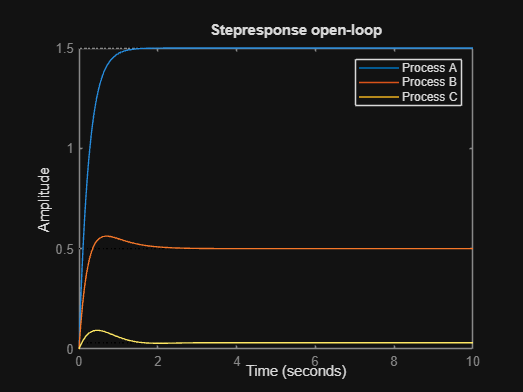

% Create one plot figure
figure;
hold on;
grid on;

step(proc_a, 10)
step(proc_b, 10)
step(proc_c, 10)

hold off
legend("Process A", "Process B", "Process C");
title('Stepresponse open-loop');

### Opdracht 2.2.2 - Stapresponsie closed-loop

defineer closed loop systemen

ClosedLoopA = ClosedLoopStep(proc_a);
ClosedLoopB = ClosedLoopStep(proc_b);
ClosedLoopC = ClosedLoopStep(proc_c);

Defineer 'k' variablen

K1 = 1;
K2 = 10;
K3 = 100;

Process A

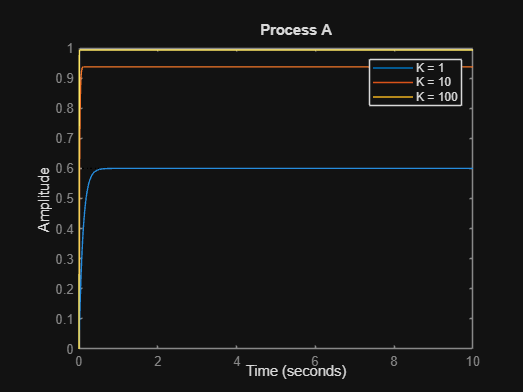

figure;
hold on;
step(ClosedLoopA(K1), 10)
step(ClosedLoopA(K2), 10)
step(ClosedLoopA(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process A");

Process B

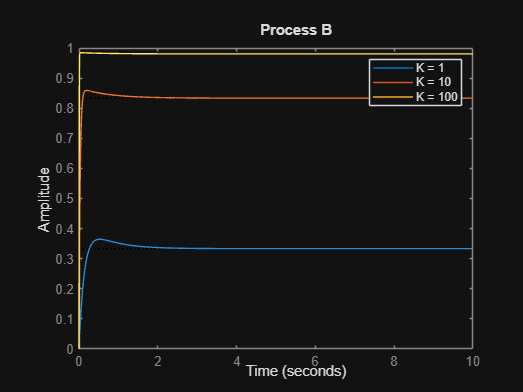

figure;
hold on;
step(ClosedLoopB(K1), 10)
step(ClosedLoopB(K2), 10)
step(ClosedLoopB(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process B");

Process C

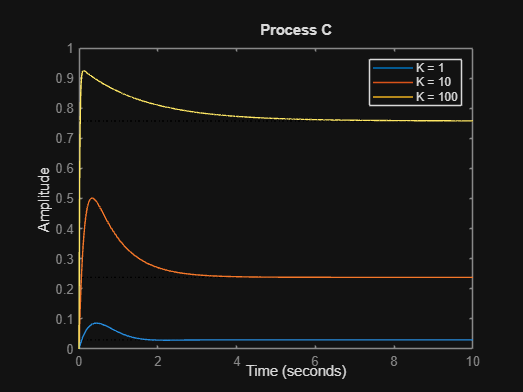

figure;
hold on;
step(ClosedLoopC(K1), 10)
step(ClosedLoopC(K2), 10)
step(ClosedLoopC(K3), 10)
hold off;
legend("K = 1", "K = 10", "K = 100")
title("Process C");

## Opdracht 2.3 Bode diagram en polen- en nulpuntenbeeld

close all;
clear
clc;
s=tf('s');

Defineer processen

H1 = 1 / ((s+2) * (s+1));
H2 = 1/ ((2*s + 1) * (0.01*s + 1)^2);
H3 = (s^2+6*s+13)/(s^3+0.2*s^2+s);

Bode plot H1

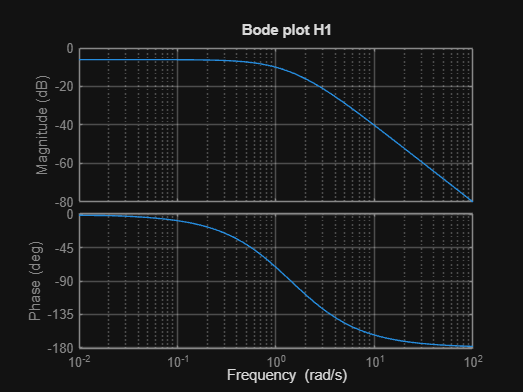

figure;
bode(H1);
title("Bode plot H1");
grid on;


Hcl = ClosedLoopStep(H1);

Hcl(1)

ans =
 
        1
  -------------
  s^2 + 3 s + 3
 
Continuous-time transfer function.
Model Properties


At phase = -45°, ω = 0.5616 rad/s, K = 0.4197 (-7.54 dB)


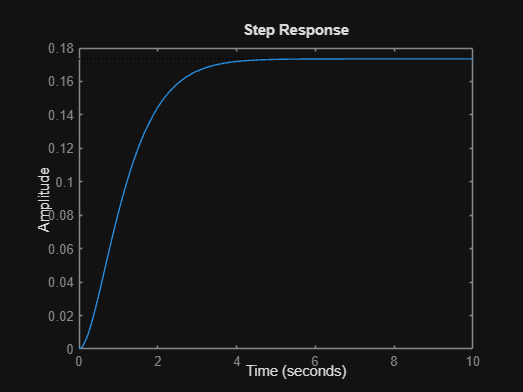

Dynamic system has an overshoot of 0.0000


BodePlotSys(H1);

Bode plot H2

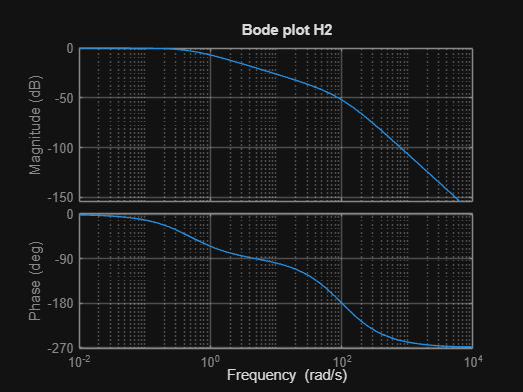

figure;
bode(H2);
title("Bode plot H2");
grid on;

At phase = -45°, ω = 0.4903 rad/s, K = 0.7140 (-2.93 dB)


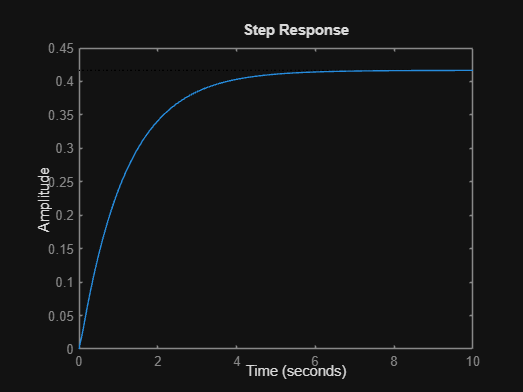

Dynamic system has an overshoot of 0.0000


BodePlotSys(H2);

Bode plot H3

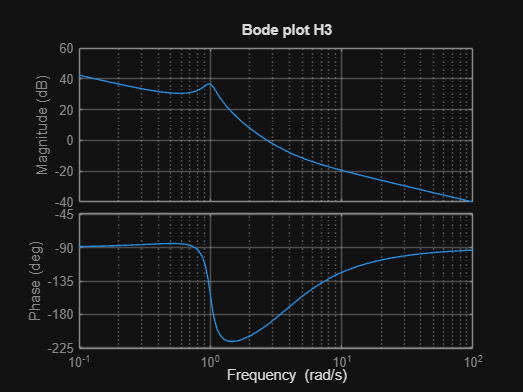

figure;
bode(H3);
title("Bode plot H3");
grid on;

At phase = -45°, ω = 1.0546 rad/s, K = 53.4386 (34.56 dB)


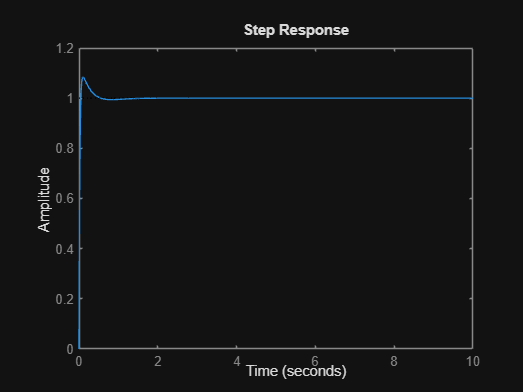

Dynamic system has an overshoot of 8.3621


BodePlotSys(H3);

rlocus plot H1

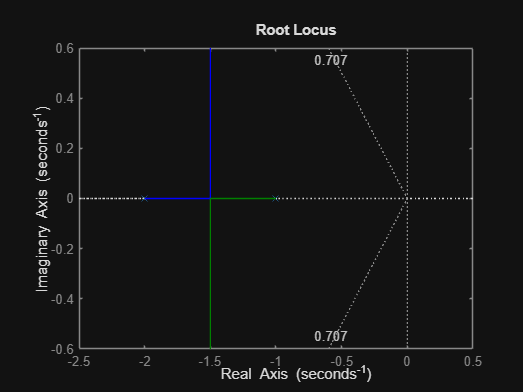

figure; 
rlocus(H1);
sgrid(0.707, 0);


k = 1 / abs(evalfr(H1, -1.5))

k = 0.2500

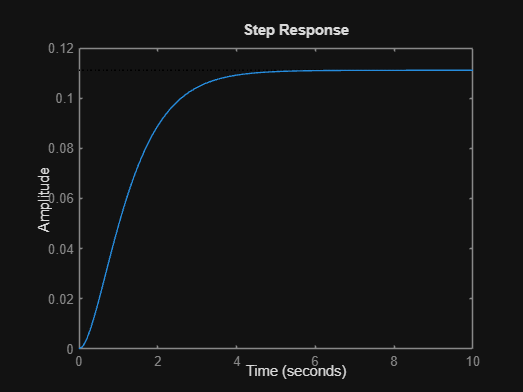


trans = ClosedLoopStep(H1);
step(trans(k), 10);

stepinfo(trans(k)).Overshoot

ans = 0

rlocus plot H2

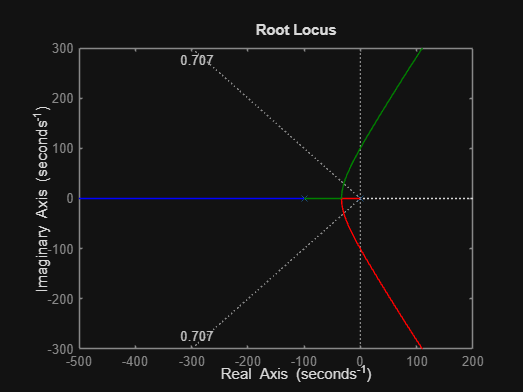

figure; 
rlocus(H2);
sgrid(0.707, 0);


pole(H2)

ans = -100.0000 + 0.0000i
-100.0000 - 0.0000i
  -0.5000 + 0.0000i



k = 1 / abs(evalfr(H2, -30))

k = 28.9100

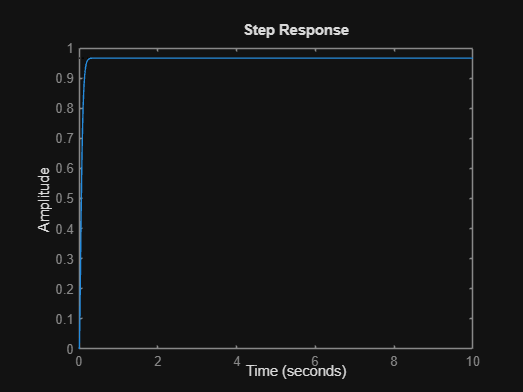


trans = ClosedLoopStep(H2);
step(trans(k), 10);

stepinfo(trans(k)).Overshoot

ans = 0

rlocus plot H3

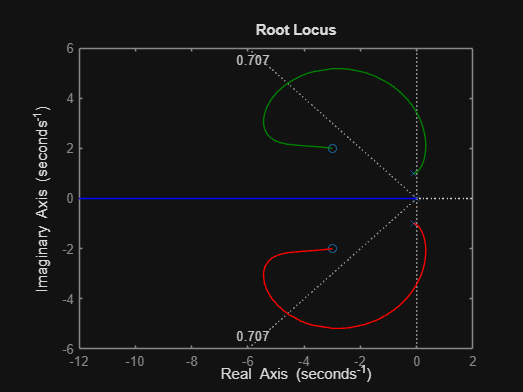

figure; 
rlocus(H3);
sgrid(0.707, 0);


pole(H3)

ans =    0.0000 + 0.0000i
  -0.1000 + 0.9950i
  -0.1000 - 0.9950i



k = 1 / abs(evalfr(H3, -4.6))

k = 14.8939

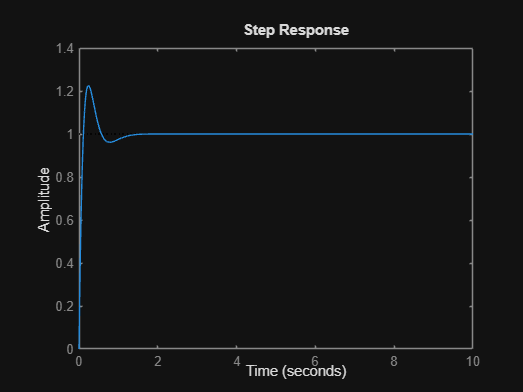


trans = ClosedLoopStep(H3);
step(trans(k), 10);

stepinfo(trans(k)).Overshoot

ans = 22.5397

## Helper functies

### Closed-loop step

function transfer = ClosedLoopStep(Process)
    ol = @(k) series(k,Process);
    back = 1;

    transfer = @(n) feedback(ol(n),back);
end

### Bode plot function

function trans = BodePlotSys(sys)
    % Calculate the DC gain at phase of -45Deg
    target_phase = -45;
    
    phase_fun = @(w) (angle(freqresp(sys, w)) * 180/pi) - target_phase;
    
    % Find frequency
    w_at_45 = fzero(phase_fun, 1);  % initial guess 1 rad/s
    
    % Evaluate magnitude
    G = freqresp(sys, w_at_45);
    mag = abs(G);
    fprintf('At phase = -45°, ω = %.4f rad/s, K = %.4f (%.2f dB)\n', ...
        w_at_45, mag, 20*log10(mag));


    trans = ClosedLoopStep(sys);
    step(trans(mag), 10);
    
    % Overshoot
    info = stepinfo(trans(mag));
    fprintf("Dynamic system has an overshoot of %.4f", info.Overshoot);
end